g=9.81;
mg=3;
close all
v=(0:34.3:1029)

v =                          0                      34.3                      68.6                     102.9                     137.2                     171.5                     205.8                     240.1                     274.4                     308.7                       343                     377.3                     411.6                     445.9                     480.2                     514.5                     548.8                     583.1                     617.4                     651.7                       686                     720.3                     754.6                     788.9                     823.2                     857.5                     891.8                     926.1                     960.4                     994.7                      1029


turnradius=(v.^2)./(mg*g)

turnradius =                          0          39.9758749575263          159.903499830105          359.782874617737          639.613999320421          999.396873938158          1439.13149847095          1958.81787291879          2558.45599728169          3238.04587155963          3997.58749575263          4837.08086986069          5756.52599388379          6755.92286782195          7835.27149167516          8994.57186544343          10233.8239891267          11553.0278627251          12952.1834862385           14431.290859667          15990.3499830105          17629.3608562691          19348.3234794427          21147.2378525314          23026.1039755352           24984.921848454          27023.6914712878          29142.4128440367          31341.0859667006          33619.7108392797          35978.2874617737


vv=[-flip(v) v]

vv =                      -1029                    -994.7                    -960.4                    -926.1                    -891.8                    -857.5                    -823.2                    -788.9                    -754.6                    -720.3                      -686                    -651.7                    -617.4                    -583.1                    -548.8                    -514.5                    -480.2                    -445.9                    -411.6                    -377.3                      -343                    -308.7                    -274.4                    -240.1                    -205.8                    -171.5                    -137.2                    -102.9                     -68.6                     -34.3                         0                         0                      34.3                      68.6                     102.9                     137.2                     171.5                     205.8       

turnrad=[flip(turnradius) turnradius]

turnrad =           35978.2874617737          33619.7108392797          31341.0859667006          29142.4128440367          27023.6914712878           24984.921848454          23026.1039755352          21147.2378525314          19348.3234794427          17629.3608562691          15990.3499830105           14431.290859667          12952.1834862385          11553.0278627251          10233.8239891267          8994.57186544343          7835.27149167516          6755.92286782195          5756.52599388379          4837.08086986069          3997.58749575263          3238.04587155963          2558.45599728169          1958.81787291879          1439.13149847095          999.396873938158          639.613999320421          359.782874617737          159.903499830105          39.9758749575263                         0                         0          39.9758749575263          159.903499830105          359.782874617737          639.613999320421          999.396873938158          1439.13149847095  

figure
hold on
title('Target Max G Turn Radius')
plot(v,turnradius)
ylabel('Turn Radius (m)')
xlabel('Velocity m/s')
hold off


maxalt=9144;

%title('Manuvering Range')
%plot(vv,turnrad)
%camroll(-90)
%set(gca, 'ydir', 'reverse')

vlock=linspace(167, 1029, 6);
trl=(vlock.^2)./(mg*g)

trl =           947.638464152226          3914.11348963643          8900.41590214067           15906.545701665          24932.5028882093          35978.2874617737


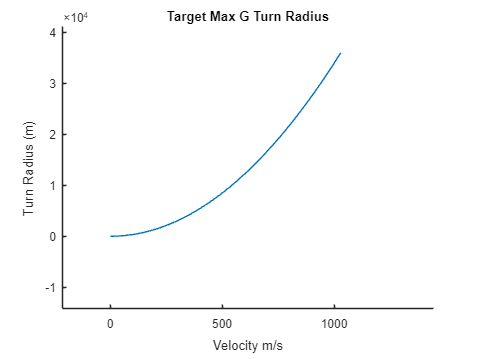

t=linspace(0, pi/2, 1000);

[x,y]=pol2cart(t, trl(1));
[x2,y2]=pol2cart(t, trl(2));
[x3,y3]=pol2cart(t, trl(3));
[x4,y4]=pol2cart(t, trl(4));
[x5,y5]=pol2cart(t, trl(5));
[x6,y6]=pol2cart(t, trl(6));
mkm=8.04672;
ftkm=9.144;
figure
hold on
plot(x/1000,y/1000)
plot(x2/1000,y2/1000)
plot(x3/1000,y3/1000)
plot(x4/1000,y4/1000)
plot(x5/1000,y5/1000)
plot(x6/1000,y6/1000)
title('Turn Radius by Mach Number')
xlabel('Turn Radius (km)')
ylabel('Turn Radius (km)')
legend('Mach 0.5' ,'Mach 1', 'Mach 1.5', 'Mach 2', 'Mach 2.5', 'Mach 3')

hold off

%radius more zoomed in on things within the kill area
%irrelevent if it can turn 90 in the box
%ground covered by slight turns within box
%angle covered by object turning burn 10 sec
%or by the time it leaves our area
%%

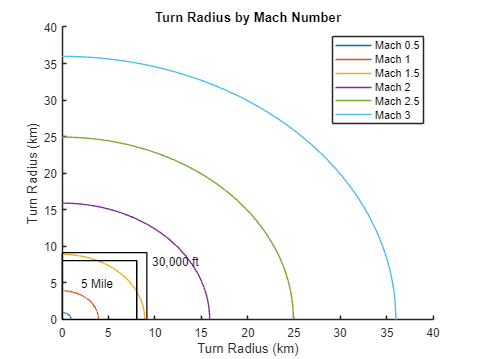


figure
hold on 
plot(x/1000,y/1000)
plot(x2/1000,y2/1000)
plot(x3/1000,y3/1000)
plot(x4/1000,y4/1000)
plot(x5/1000,y5/1000)
plot(x6/1000,y6/1000)
rectangle('Position',[0 0 mkm mkm])
text(2,5,'5 Mile')
rectangle('Position',[0 0 ftkm ftkm])
text(ftkm+0.5,8,'30,000 ft')
title('Turn Radius by Mach Number')
xlabel('Turn Radius (km)')
ylabel('Turn Radius (km)')
legend('Mach 0.5' ,'Mach 1', 'Mach 1.5', 'Mach 2', 'Mach 2.5', 'Mach 3')

hold off


%turn radius which completes 90deg turn within operational area
voparea=linspace(10, 514.5, 5);
troparea=(voparea.^2)./(mg*g)

troparea =           3.39789330615019          629.630160550459          2336.90324498811           5125.2171466191          8994.57186544343


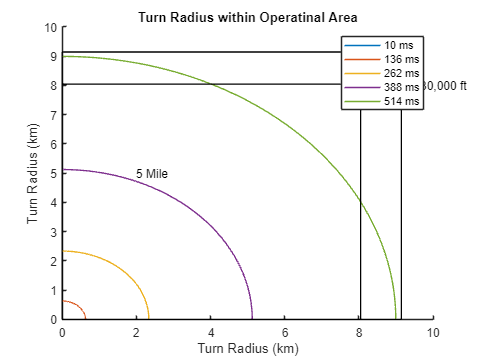


[x,y]=pol2cart(t, troparea(1));
[x2,y2]=pol2cart(t, troparea(2));
[x3,y3]=pol2cart(t, troparea(3));
[x4,y4]=pol2cart(t,troparea(4));
[x5,y5]=pol2cart(t, troparea(5));


figure 
hold on 
plot(x/1000,y/1000)
plot(x2/1000,y2/1000)
plot(x3/1000,y3/1000)
plot(x4/1000,y4/1000)
plot(x5/1000,y5/1000)
rectangle('Position',[0 0 mkm mkm])
text(2,5,'5 Mile')
rectangle('Position',[0 0 ftkm ftkm])
text(ftkm+0.5,8,'30,000 ft')
title('Turn Radius within Operatinal Area')
xlabel('Turn Radius (km)')
ylabel('Turn Radius (km)')
legend('10 ms', '136 ms', '262 ms' ,'388 ms', '514 ms')
hold off

[x,y]=pol2cart(t, trl(1));
[x2,y2]=pol2cart(t, trl(2));
[x3,y3]=pol2cart(t, trl(3));
[x4,y4]=pol2cart(t, trl(4));
[x5,y5]=pol2cart(t, trl(5));
[x6,y6]=pol2cart(t, trl(6));
figure 
hold on 
plot(x/1000-((x/1000)-1),y/1000)
plot(x2/1000-((x2/1000)-1),y2/1000)
plot(x3/1000-((x3/1000)-1),y3/1000)
plot(x4/1000-((x4/1000)-1),y4/1000)
plot(x5/1000-((x5/1000)-1),y5/1000)
plot(x6/1000-((x6/1000)-1),y6/1000)

hold off
